**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% load camera parameters
load('../../Camera_Kalibrierung\Cam_Param_1.mat');

% unpack principal point, image dimensions and intrinsic camera matrix
principalPoint = int64(cameraParams.PrincipalPoint);
imageDimensions = cameraParams.ImageSize;
cameraIntrinsics = cameraParams.Intrinsics;

% read the image of the checkerboard
image = imread('.\Images\04_lab_checkerboard_Color.png');

**CALCULATE THE CHECKERBOARD POSITION**

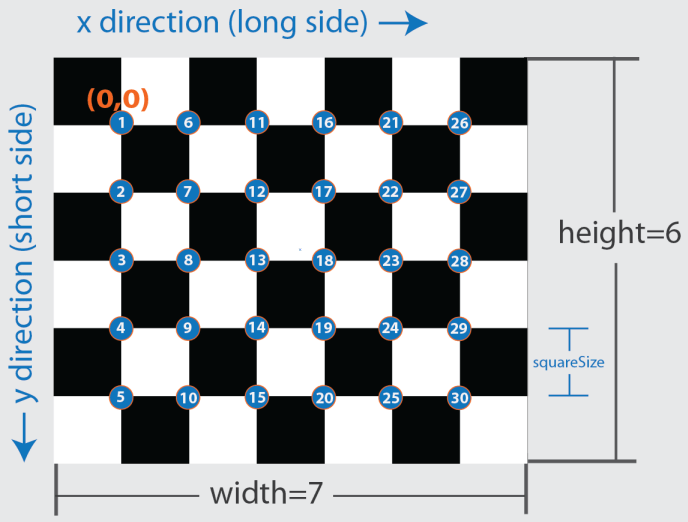

% identify the points of intersection in the checkerboard pattern and
% return them as a list of xy coordinates.
% https://de.mathworks.com/help/vision/ref/detectcheckerboardpoints.html#responsive_offcanvas
[checkerboardImagePoints, checkerboardSize] = detectCheckerboardPoints(image);

% define the physical dimensions of a checkerboard square in millimeters.
squareSize = 30;

% generate the coordinates of the points of intersection within the
% checkerboard pattern. The unit is determined by the unit chosen in
% squareSize.
% https://de.mathworks.com/help/vision/ref/generatecheckerboardpoints.html#responsive_offcanvas
checkerboardPatternPoints = generateCheckerboardPoints(checkerboardSize, squareSize);


% get the world coordinates xy of the checkerboard points of intersection
checkerboardWorldPoints = getCheckerboardInCCS(checkerboardImagePoints, checkerboardPatternPoints, ...
    checkerboardSize, principalPoint);

% estimate an extrinsic transformation matrix
% https://de.mathworks.com/help/vision/ref/estimateextrinsics.html#responsive_offcanvas
cameraExtrinsics = estimateExtrinsics(checkerboardImagePoints, checkerboardWorldPoints, cameraIntrinsics);

% check the transformed checkerboard diagonal against an ideal diagonal calculated from the checkerboard metadata
match = checkPlausability(checkerboardImagePoints, cameraExtrinsics, cameraIntrinsics, checkerboardSize, squareSize)

match = 100.6166

**VISUALIZATION**

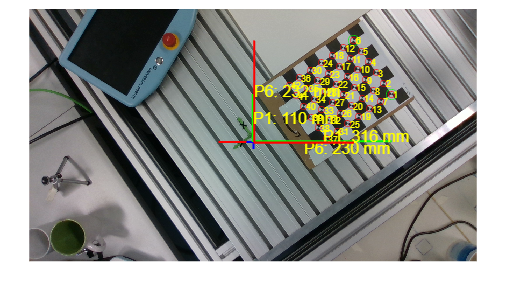

% Display the image and plot the detected corners and axes.
imshow(image);
hold on;

drawCCS(principalPoint, 100);
drawImagePoints(checkerboardImagePoints);
drawCBCS(checkerboardImagePoints, checkerboardSize);

% highlight the origin and point 6 with green circles.
highlightPoint(checkerboardImagePoints, 1)
highlightPoint(checkerboardImagePoints, 6)

% measure the real world distances along the x and y axis of the ccs and
% visualize them
measurePointAndPlot(checkerboardImagePoints, 1, principalPoint, cameraExtrinsics, cameraIntrinsics, 4);
measurePointAndPlot(checkerboardImagePoints, 6, principalPoint, cameraExtrinsics, cameraIntrinsics, -4);

hold off;

**CHECKERBOARD POINTS OF INTERSECTION IN CCS**

function checkerboardWorldPoints = getCheckerboardInCCS(checkerboardImagePoints, checkerboardPatternPoints, checkerboardSize, principalPoint)

dimensionX = checkerboardSize(2) - 1;
dimensionY = checkerboardSize(1) - 1;

% get the real square edge length from an arbitrary adjacent pair of checkerboard pattern points
squareSizeReal = norm(checkerboardPatternPoints(1,:) - checkerboardPatternPoints(2,:));

% calculate the list length
n = dimensionX * dimensionY;

% initialize lists of length n 
pixelDistancesX = eye(n, 1);
pixelDistancesY = eye(n,1);

% get the image square edge lengths as mean pixel distance between the
% adjacent checkerboard image points
for i = 1:n
    if i <= (n - dimensionY)
        to = i + dimensionY;
        pixelDistancesX(i) = norm(checkerboardImagePoints(i,:) - checkerboardImagePoints(to,:));
    else
        pixelDistancesX(i) = NaN;
    end
    if mod(i, dimensionY) ~= 0
        pixelDistancesY(i) = norm(checkerboardImagePoints(i,:) - checkerboardImagePoints(i+1,:));
    else
        pixelDistancesY(i) = NaN;
    end
end

squareSizeImage = mean(cat(1, pixelDistancesX, pixelDistancesY), 'omitnan');

% calculate a scaling factor from the ratio of the square edge lengths
scalingFactor = squareSizeReal / squareSizeImage;

checkerboardWorldPoints = (double(principalPoint) - checkerboardImagePoints) * scalingFactor;
end

**PLOT IMAGE POINTS AS CIRCLES**

function drawImagePoints(imagePoints)

offset = 5;

% draw circles around the points of intersection
plot(imagePoints(:, 1), imagePoints(:, 2), 'ro');

% label these circles with their index
for i = 1:size(imagePoints, 1)
    text(imagePoints(i, 1) + offset, imagePoints(i, 2), num2str(i), 'Color', 'y', 'FontSize', 8);
end
end

**PLOT CAMERA COORDINATE SYSTEM**

function drawCCS(principalPoint, axisLength)

offset = 5;

% construct the three points to draw a 2d coordinate frame
framePoints = [principalPoint; principalPoint; principalPoint];
framePoints(1,1) = framePoints(1,1) - axisLength;
framePoints(3,2) = framePoints(3,2) - axisLength;

% draw the x axis in red
line(framePoints(1:2,1), framePoints(1:2,2), 'Color', 'r', 'LineWidth', 2);
% draw the y axis in green
line(framePoints(2:3,1), framePoints(2:3,2), 'Color', 'g', 'LineWidth', 2);
% write the frame name aside the axes
text(framePoints(2,1) + offset, framePoints(2,2), 'CCS', 'Color', 'b', 'FontSize', 8);
end

**PLOT CHECKERBOARD COORDINATE SYSTEM**

function drawCBCS(imagePoints, checkerboardSize)

offset = 10;

% construct the three points to draw a 2d coordinate frame
framePoints = [imagePoints(checkerboardSize(1),:); imagePoints(1,:); imagePoints(2,:)];

% draw the x axis in red
line(framePoints(1:2,1), framePoints(1:2,2), 'Color', 'r', 'LineWidth', 2);
% draw the y axis in green
line(framePoints(2:3,1), framePoints(2:3,2), 'Color', 'g', 'LineWidth', 2);
% write the frame name aside the axes
text(framePoints(2,1) + offset, framePoints(2,2), 'CBCS', 'Color', 'y', 'FontSize', 8);
end

function highlightPoint(imagePoints, index)
plot(imagePoints(index, 1), imagePoints(index, 2), 'go', 'MarkerSize', 10);
end

**MEASURE POINT DISTANCE TO PRINCIPLE POINT AND PLOT**

function measurePointAndPlot(imagePoints, index, principalPoint, cameraExtrinsics, cameraIntrinsics, scetchOffset)

imagePoint = imagePoints(index,:);
principalPoint = double(principalPoint);

% transform the principal point to the ccs
principalWorldPoint = img2world2d(principalPoint, cameraExtrinsics, cameraIntrinsics);

% transform the chosen point to the ccs
imageWorldPoint = img2world2d(imagePoint, cameraExtrinsics, cameraIntrinsics);

% get both the pixel and real world distances between principal point and
% the selected image point
pixelDistance = imagePoint - principalPoint;
worldDistance = imageWorldPoint - principalWorldPoint;

% manage the offset for visualization ...
offPrincipalPoint = principalPoint + scetchOffset;
xPoint = offPrincipalPoint + [pixelDistance(1) 0];
yPoint = offPrincipalPoint + [0 pixelDistance(2)];

% ... and merge the frame points
framePoints = [xPoint; offPrincipalPoint; yPoint];

% plot the distances and labels in a random color
color = [rand,rand,rand];
plot(framePoints(:,1), framePoints(:,2), 'Color', color, 'LineWidth', 2);
text(framePoints(1,1), framePoints(1,2), ['P', num2str(index), 'X: ', num2str(abs(int64(worldDistance(1)))), ' mm'], 'Color', color, 'FontSize', 15);
text(framePoints(3,1), framePoints(3,2), ['P', num2str(index), 'Y: ', num2str(abs(int64(worldDistance(2)))), ' mm'], 'Color', color, 'FontSize', 15);
end

**CHECK PLAUSABILITY OF CALCULATED CAMERA EXTRINSICS**

function match = checkPlausability(imagePoints, cameraExtrinsics, cameraIntrinsics, checkerboardSize, squareSize)

dimensionX = checkerboardSize(2) - 2;
dimensionY = checkerboardSize(1) - 2;

idealDiagonal = sqrt(dimensionX^2 + dimensionY^2) * squareSize;

diagonalPoints = [imagePoints(1,:); imagePoints((dimensionX + 1)*(dimensionY + 1), :)];
diagonalWorldPoints = img2world2d(diagonalPoints, cameraExtrinsics, cameraIntrinsics);

approxDiagonal = norm(diagonalWorldPoints(1, :) - diagonalWorldPoints(2, :));

match = 100 * approxDiagonal / idealDiagonal;
end